## **Reflectometer Script**

clear; close all; clc;

%% ---------------- Antenna (.s1p) ----------------
s1pFile = 'AntennaVNA.s1p';
sObj = sparameters(s1pFile);

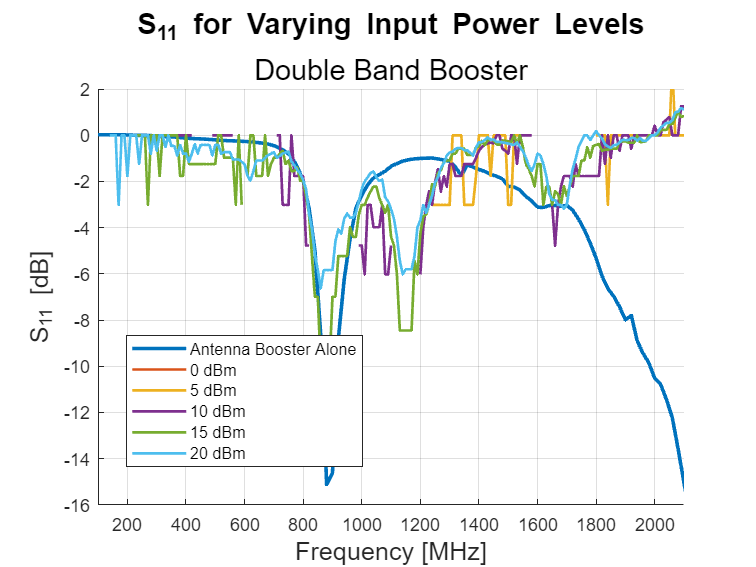

freq_Hz = sObj.Frequencies;
S11     = rfparam(sObj,1,1);

S11_dB   = 20*log10(abs(S11));
freq_MHz = freq_Hz/1e6;

figure; hold on; grid on;
plot(freq_MHz, S11_dB, 'LineWidth', 2, ...
    'DisplayName', 'Antenna Alone');

%% ---------------- Excel Files medidas_XdBm ----------------
values_dBm = 0:5:20;

for p = values_dBm
    fname = sprintf('measures_%ddBm.xlsx', p);
    if ~isfile(fname)
        warning('%s not found. Omitted.', fname);
        continue;
    end

    T = readtable(fname);

    f_MHz        = T.f;
    m1p_coupled  = T.m1p_coupled;
    m1p_isolated = T.m1p_isolated;

    S11_meas_dB = 10*log10(m1p_isolated ./ m1p_coupled);

    plot(f_MHz, S11_meas_dB, 'LineWidth', 1.5, ...
        'DisplayName', sprintf('%d dBm', p));
end

xlabel('Frequency [MHz]', 'FontSize', 14);
ylabel('S_{11} [dB]',      'FontSize', 14);
title('S_{11} for Varying Input Power Levels','FontSize', 16);
ylim([-16 2]);
xlim([100 2100]);

% ----- Interactive legend: click to show/hide each curve -----
hLeg = legend('show','Location','best');
hLeg.ItemHitFcn = @legendToggle;

grid on;
hold off;

drawnow;




## ---------- Local function: toggles the visibility of the curve ----------

function legendToggle(~,event)
    if strcmp(event.Peer.Visible,'on')
        event.Peer.Visible = 'off';
    else
        event.Peer.Visible = 'on';
    end
end



